Alberto Javier Pelayo Brambila - A01636406

**Part 1**. Select some problems and solve. 75 points MAX. The parameters for this section are:

𝒂=19, 𝒃=8 and 𝒄=𝑏+1=9

**System 1**

a=19;
b=8;
c=b+1;
G=tf([a],[b c])

G =
 
    19
  -------
  8 s + 9
 
Continuous-time transfer function.



%step(G)
GN=tf([a/c],[b/c c/c])

GN =
 
     2.111
  ------------
  0.8889 s + 1
 
Continuous-time transfer function.



**Characterization of the system in open loop.** 

input u(t)=b=8

The final value

u=b

u = 8

yss=(a/c)*u

yss = 16.8889

settling time 

T=b/c;
tss=5*T

tss = 4.4444

 damping factor, 

IT DOESN'T HAVE DAMPING FACTOR

Natural frequency 

IT DOESN'T HAVE 

 Damped Natural Frequency. Assume the input u(t)=b.

IT DOESN'T HAVE 

**Characterization of the system. **The final value in closed loop with a control gain K=a=19 and a reference r(t)=c=9.

k=a

k = 19

r=c

r = 9

Gcl=r*tf([k*a],[b c+(k*a)])

Gcl =
 
    3249
  ---------
  8 s + 370
 
Continuous-time transfer function.



%step(Gcl)
ysscl=[(k*a)/(c+(k*a))]*r

ysscl = 8.7811

**Gain range for stability.** The set of gains for which the system is stable in closed loop.

%sisotool(G);

Gain range [4.7368e-05, +inf)

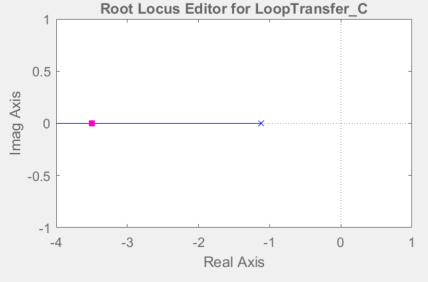

**System 2**

G2=tf([a*c*(-0.004/2) a*c],[7 3*(b/15) c*c ])

G2 =
 
    -0.342 s + 171
  ------------------
  7 s^2 + 1.6 s + 81
 
Continuous-time transfer function.



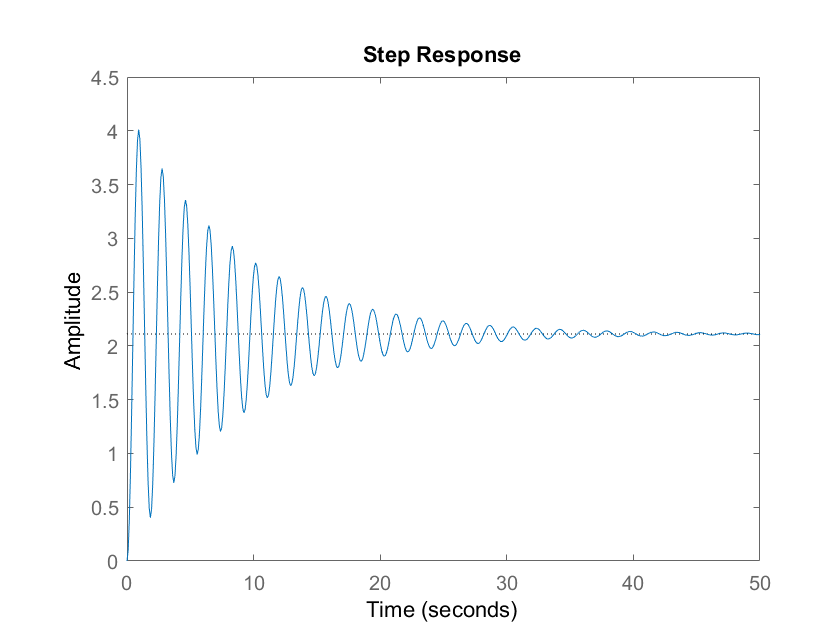

step(G2)

**Characterization of the system in open loop.** 

The final value

G2N=tf([-0.342/7 171/7], [1 1.6/7 81/7])

G2N =
 
    -0.04886 s + 24.43
  ----------------------
  s^2 + 0.2286 s + 11.57
 
Continuous-time transfer function.



%step(G2);
yss2=(171/81)*u

yss2 = 16.8889

Natural Frequency

wn2=sqrt(11.57)

wn2 = 3.4015

d2=0.2286/(2*wn2)

d2 = 0.0336

settling time 

tss2_2=(4/(d2*wn2))

tss2_2 = 34.9956

tss2_5=(3/(d2*wn2))

tss2_5 = 26.2467

Damped Natural Frequency

wd2=wn2*sqrt(1-(d2)^2)

wd2 = 3.3995

**Characterization of the system. **The final value in closed loop with a control gain K=a and a reference r(t)=c.

G2cl=r*tf([-0.342 171*k],[7 1.6 (81)+(k*171)])

G2cl =
 
    -3.078 s + 29241
  --------------------
  7 s^2 + 1.6 s + 3330
 
Continuous-time transfer function.



yss2cl=r*(171*k)/((81)+(k*171))

yss2cl = 8.7811

**Gain range for stability.** The set of gains for which the system is stable in closed loop.

%sisotool(G2);

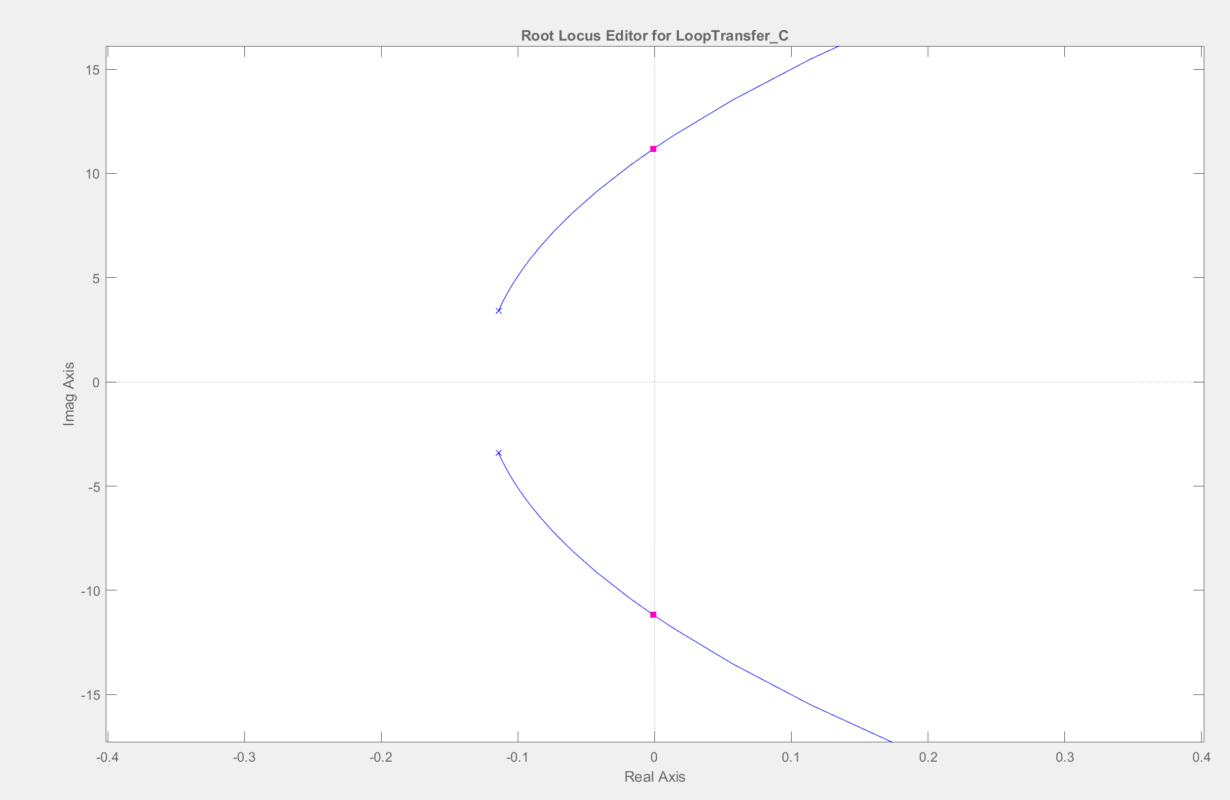

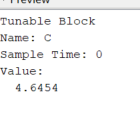

**System 3**

G3 = tf([7*c*(-0.006/2) 7*c],[1 3*b 2*b^2])

G3 =
 
   -0.189 s + 63
  ----------------
  s^2 + 24 s + 128
 
Continuous-time transfer function.



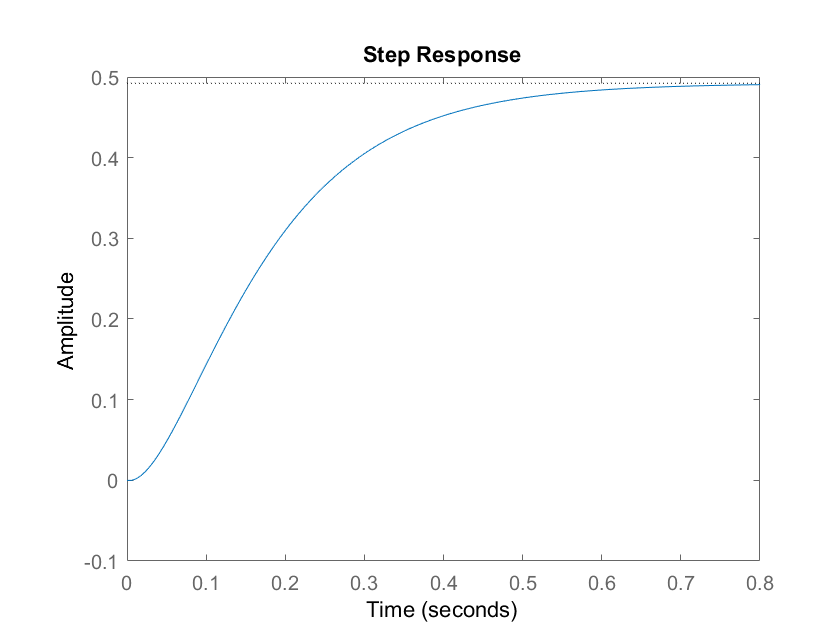

step(G3)

**Characterization of the system in open loop.** 

The final value

yss3=(63/128)*u

yss3 = 3.9375

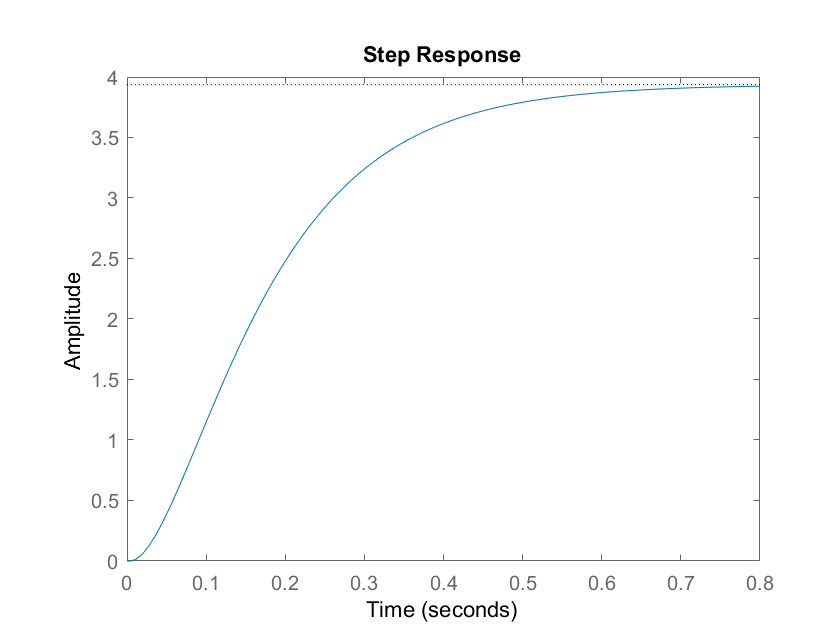

step(G3*u)

Natural Frequency

wn3=sqrt(128)

wn3 = 11.3137

d3=24/(2*wn3)

d3 = 1.0607

settling time 

tss3_2=(4/(d3*wn3))

tss3_2 = 0.3333

tss3_5=(3/(d3*wn3))

tss3_5 = 0.2500

Damped Natural Frequency

wd3_1=(-2*b)/(d3 + sqrt(d3^2-1))

wd3_1 = -11.3137

wd3_2=(-2*b)/(d3 - sqrt(d3^2-1))

wd3_2 = -22.6274

**Characterization of the system. **The final value in closed loop with a control gain K=a and a reference r(t)=c.

G3cl=r*tf([-0.189 63*k],[1 24 (128)+(k*63)])

G3cl =
 
  -1.701 s + 10773
  -----------------
  s^2 + 24 s + 1325
 
Continuous-time transfer function.



yss3cl=r*(63*k)/((128)+(k*63))

yss3cl = 8.1306

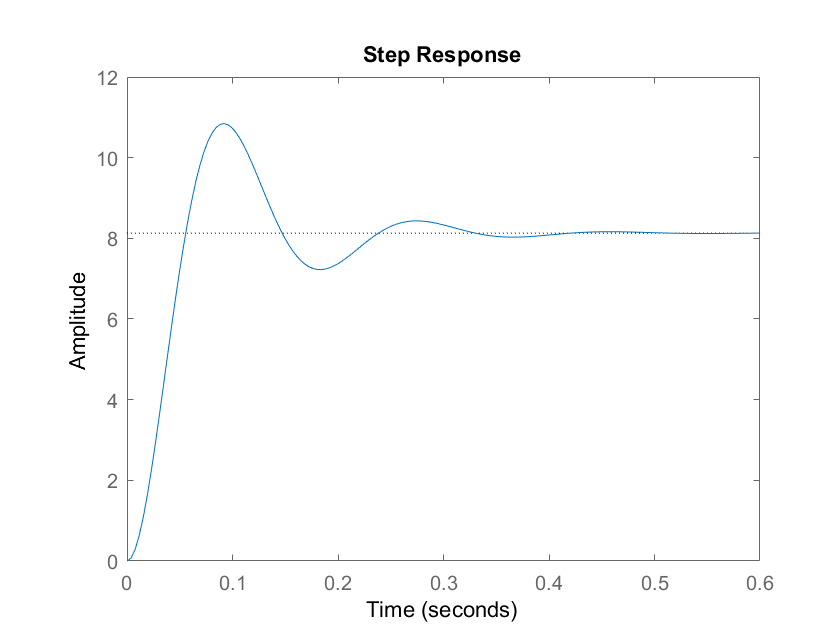

step(G3cl)

**Gain range for stability.** The set of gains for which the system is stable in closed loop.

%sisotool(G3);